# Short introduction to the Generalized Extreme Values (GEV) distribution

## Summary

In this script, some of the results presented by John D. Holmes in the first part of the chapter 2 of his book [1] are reproduced .  The notations used in[1] differ slightly from those used with the Matlab statistics toolbox. In particular, the expression of the cumulative density function of the GEV he uses is based on the shape factor k whereas the statistical toolbox uses "K = -k". To keep consistent with the Matlab notations, the convention "K = -k" is also used herein.

####  **References**

 [1] Holmes, J. D. (2015). Wind loading of structures. CRC Press.

## Example 1

 The figure plotted here reproduces the one shown in Fig 2.1 in [1]

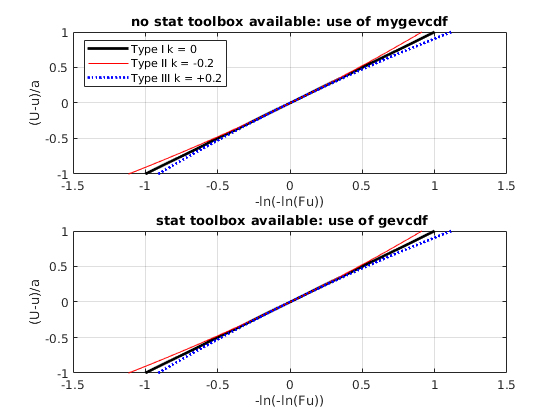

clearvars;close all;clc;
K = [0,0.2,-0.2]; % 3 types of GEV distributions (K<0, K=0 and K>0)
N = 100;
a = 1;
u = 1;
U = linspace(0,2,N); 

% Check if statistic toolbox exists
status = license('test','statistics_toolbox');if status==0, warning('No satistics toolbox detected');end


F = zeros(3,N);
for ii=1:numel(K)
    F(ii,:) = mygevcdf(U,K(ii),a,u); % if no stat toolbox available
end

figure
subplot(211)
hold on;box on;
plot(-log(-log(F(1,:))),(U-u)./a,'k','linewidth',2);
plot(-log(-log(F(2,:))),(U-u)./a,'r','linewidth',0.7);
plot(-log(-log(F(3,:))),(U-u)./a,'b:','linewidth',2);
grid on
xlabel('-ln(-ln(Fu))')
ylabel('(U-u)/a')
legend('Type I k = 0','Type II k = -0.2','Type III k = +0.2',...
    'location','Northwest')
title('no stat toolbox available: use of mygevcdf')

if status ==1
    F = zeros(3,N);
    for ii=1:3
        F(ii,:)  = gevcdf(U,K(ii),a,u); % if stat toolbox is available
    end
    
    subplot(212)
    hold on;box on;
    plot(-log(-log(F(1,:))),(U-u)./a,'k','linewidth',2);
    plot(-log(-log(F(2,:))),(U-u)./a,'r','linewidth',0.7);
    plot(-log(-log(F(3,:))),(U-u)./a,'b:','linewidth',2);
    grid on
    xlabel('-ln(-ln(Fu))')
    ylabel('(U-u)/a')
    title(' stat toolbox available: use of gevcdf')
end


set(gcf,'color','w')

## Example 2

The data used (EastSale.mat) in this example comes from page 42-43 in [1]. The extreme 10  min win velocities are calculated for different return periods, and different methods. The matlab built-in function provided with the statistical toolbox is compared to the one used here.


load EastSale
if status ==1
    [parmhat0,parmci0] = gevfit(meanU); % Matlab built-in function
else
    parmhat0 = nan;
    parmci0 = nan;
end

% Home-made function
[parmhat1] = fitGEV(meanU,'method','Gumbel');
[parmhat2] = fitGEV(meanU,'method','moments');
[parmhat3] = fitGEV(meanU,'method','Gringorten');

fprintf('Parameters found: \n')

Parameters found: 


disp(['--------------------------------------------------------------------------------------------'])

--------------------------------------------------------------------------------------------


disp(['Method          ','Gumbel' ,'     moments','     Gringorten','     gevfit (Matlab)'])

Method          Gumbel     moments     Gringorten     gevfit (Matlab)


disp(['--------------------------------------------------------------------------------------------'])

--------------------------------------------------------------------------------------------


disp(['k','               ',num2str(parmhat1(1),4),'         ',num2str(parmhat2(1),4),'            ',num2str(parmhat3(1),4),'             ',num2str(parmhat0(1),4)])

k               0         0            0             -0.001661


disp(['mu','              ',num2str(parmhat1(2),4),'     ',num2str(parmhat2(2),4),'        ',num2str(parmhat3(2),4),'          ',num2str(parmhat0(2),4)])

mu              2.659     2.492        2.513          2.421


disp(['sigma','           ',num2str(parmhat1(3),4),'     ',num2str(parmhat2(3),4),'        ',num2str(parmhat3(3),4),'          ',num2str(parmhat0(3),4)])

sigma           27.81     27.83        27.84          27.89


disp(['--------------------------------------------------------------------------------------------'])

--------------------------------------------------------------------------------------------


fprintf('\n\n')
% cdf of GEV
X = linspace(min(meanU),3*max(meanU),1e4); % Measured
F0  = mygevcdf(X,parmhat0(1),parmhat0(2),parmhat0(3)); % matlab
F1  = mygevcdf(X,parmhat1(1),parmhat1(2),parmhat1(3)); % Gumbel
F2  = mygevcdf(X,parmhat2(1),parmhat2(2),parmhat2(3)); % moments
F3  = mygevcdf(X,parmhat3(1),parmhat3(2),parmhat3(3)); % Gringorten
% Return period R
R(1,:)= 1./(1-F1); % Gumbel
R(2,:) = 1./(1-F3); % Gringorten
R(3,:) = 1./(1-F2); % moments
R(4,:) = 1./(1-F0); % matlab
clear ind*
% Find return period
for ii=1:4
    [~,ind_50(ii)] = min(abs(R(ii,:)-50));
    [~,ind_100(ii)] = min(abs(R(ii,:)-100));
    [~,ind_200(ii)] = min(abs(R(ii,:)-200));
    [~,ind_500(ii)] = min(abs(R(ii,:)-500));
    [~,ind_1000(ii)] = min(abs(R(ii,:)-1000));
end

fprintf('Prediction of extreme wind speeds for East Sale (synoptic winds): \n')

Prediction of extreme wind speeds for East Sale (synoptic winds): 




val = [X(ind_50);X(ind_100);X(ind_200);X(ind_500);X(ind_1000)];
disp(['--------------------------------------------------------------------------------------------'])

--------------------------------------------------------------------------------------------


disp(['Return period (years)','              Predicted       gust       speed       (m/s)'])

Return period (years)              Predicted       gust       speed       (m/s)


disp(['--------------------- ',' ------------------------------------------------------------------'])

---------------------  ------------------------------------------------------------------


disp(['       ','                  (Gumbel)','       (Gringorten)','       (moments)','       (Matlab)'])

                         (Gumbel)       (Gringorten)       (moments)       (Matlab)


disp(['50','                        ',num2str(val(1,1),3),'           ',num2str(val(1,2),3),'               ',num2str(val(1,3),3),'             ',num2str(val(1,4),3)])

50                        38.2           37.6               37.6             37.3


disp(['100','                       ',num2str(val(2,1),3),'             ',num2str(val(2,2),3),'               ',num2str(val(2,3),3),'             ',num2str(val(2,4),3)])

100                       40             39.4               39.3             39


disp(['200','                       ',num2str(val(3,1),3),'           ',num2str(val(3,2),3),'                 ',num2str(val(3,3),3),'             ',num2str(val(3,4),3)])

200                       41.9           41.1                 41             40.7


disp(['500','                       ',num2str(val(4,1),3),'           ',num2str(val(4,2),3),'               ',num2str(val(4,3),3),'             ',num2str(val(4,4),3)])

500                       44.3           43.4               43.3             42.9


disp(['1000','                      ',num2str(val(5,1),3),'           ',num2str(val(5,2),3),'                 ',num2str(val(5,3),3),'             ',num2str(val(5,4),3)])

1000                      46.2           45.2                 45             44.5


disp(['--------------------------------------------------------------------------------------------'])

--------------------------------------------------------------------------------------------


### Graphical visualization

This time the function mygevcdf is used in combination with fitGEV.

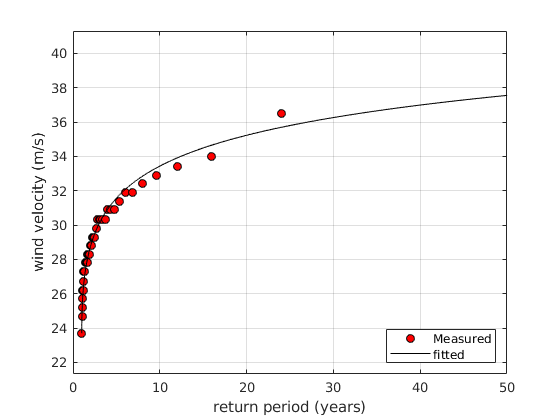

% get cdf
returnPeriod = 50;
x = ([1:numel(meanU)])/(numel(meanU)+1);
r = 1./(1-x);
X = linspace(min(meanU),2*max(meanU),1e4);

F  = mygevcdf(X,parmhat2(1),parmhat2(2),parmhat2(3)); % for fitted parameters
R = 1./(1-F);

figure
hold on;box on;
plot(r,sort(meanU),'ko','markerfacecolor','r'); % cdf of meanU
plot(R,X,'k');
xlabel('return period (years)');
ylabel('wind velocity (m/s)');
axis tight
  ylim([0.9*min(X(R<returnPeriod)),1.1*max(X(R<returnPeriod))])
    xlim([0,returnPeriod])
legend('Measured','fitted','location','SouthEast')
grid on

set(gcf,'color','w');

It is actually possible to plot directly the figure using fitGEV:

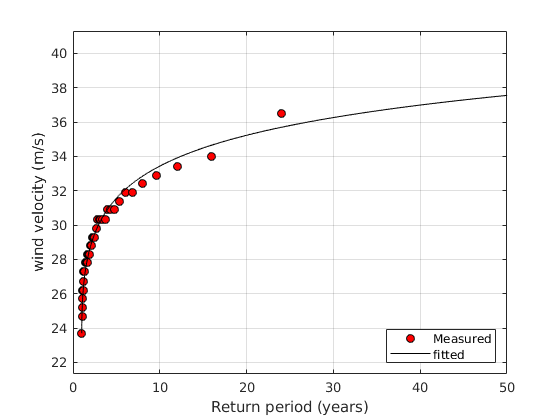

50-year hourly wind velocity is 37.6 m/s (based on 69 years of data) 


load EastSale
[parmhat2] = fitGEV(meanU,'method','moments','dataPlot',1,'returnPeriod',50);